# Interpolation - cubic spline

wiki: [https://en.wikipedia.org/wiki/Spline_(mathematics)#Natural_continuity](https://en.wikipedia.org/wiki/Spline_(mathematics)#Natural_continuity)

given a series pairs of function values $$$
x_0,x_1,...,x_N
$$
$(sorted), $$$
f_0,f_1,...,f_N
$$

$, estimate function value at some intermediate point $$x$$.

- continuous in first and second order derivatives

interval: $$$
h_i=x_{i+1}-x_i,\quad i=\text{0,1,...,}N-1
$$
$

auxiliary function: $$$
\lambda _i=\frac{x_{i+1}-x}{h_i},\quad \omega _i=1-\lambda _i,\quad i=\text{0,1,...,}N-1
$$
$

- 
$$$$
\lambda _i\left( x_i \right) =\omega _i\left( x_{i+1} \right) =1
$$
$$


- 
$$$$
\lambda _i\left( x_{i+1} \right) =\omega _i\left( x_i \right) =0
$$
$$


- 
$$$$
\lambda _{i}^{'}\left( x_i \right) =\lambda _{i}^{'}\left( x_{i+1} \right) =-\frac{1}{h_i}
$$
$$


- 
$$$$
\omega _{i}^{'}\left( x_i \right) =\omega _{i}^{'}\left( x_{i+1} \right) =\frac{1}{h_i}
$$
$$


Interpolation function: $$$
f_{\left[ x_i,x_{i+1} \right]}=f_i\lambda _i+f_{i+1}\omega _i+\frac{h_{i}^{2}f_{i}^{''}}{6}\left( \lambda _{i}^{3}-\lambda _i \right) +\frac{h_{i}^{2}f_{i+1}^{''}}{6}\left( \omega _{i}^{3}-\omega _i \right) 
$$
$

- 
$$$$
f\left( x_i \right) _{\left[ x_i,x_{i+1} \right]}=f_i
$$
$$


- 
$$$$
f\left( x_{i+1} \right) _{\left[ x_i,x_{i+1} \right]}=f_{i+1}
$$
$$


- 
$$$$
f^'\left( x_i \right) _{\left[ x_i,x_{i+1} \right]}=-\frac{f_i}{h_i}+\frac{f_{i+1}}{h_i}-\frac{h_i}{3}f_{i}^{''}-\frac{h_i}{6}f_{i+1}^{''}
$$
$$


- 
$$$$
f^'\left( x_{i+1} \right) _{\left[ x_i,x_{i+1} \right]}=-\frac{f_i}{h_i}+\frac{f_{i+1}}{h_i}+\frac{h_i}{6}f_{i}^{''}+\frac{h_i}{3}f_{i+1}^{''}
$$
$$


- 
$$$$
f^{''}\left( x_i \right) _{\left[ x_i,x_{i+1} \right]}=f_{i}^{''}
$$
$$


- 
$$$$
f^{''}\left( x_{i+1} \right) _{\left[ x_i,x_{i+1} \right]}=f_{i+1}^{''}
$$
$$


equations: $$$
h_{i-1}f_{i-1}^{''}+2\left( h_{i-1}+h_i \right) f_{i}^{''}+h_if_{i+1}^{''}=6\frac{f_{i+1}-f_i}{h_i}-6\frac{f_i-f_{i-1}}{h_{i-1}}
$$
$

Boundary condition for natural cubic spline: $$$
f_{0}^{''}=f_{N}^{''}=0
$$

$

denote: $$$
M_i=6\frac{f_{i+1}-f_i}{h_i}-6\frac{f_i-f_{i-1}}{h_{i-1}},\quad i=\text{1,2,...,}N-1
$$
$


$$$$
\left(\matrix{
	1&		&		&		&		&		\cr
	h_0&		2\left( h_0+h_1 \right)&		h_1&		&		&		\cr
	&		h_1&		2\left( h_1+h_2 \right)&		h_2&		&		\cr
	&		&		\ddots&		\ddots&		\ddots&		\cr
	&		&		&		h_{N-1}&		2\left( h_{N-1}+h_N \right)&		h_N\cr
	&		&		&		&		&		1\cr
}\right) \left( \begin{array}{c}
	f_{0}^{''}\\
	f_{1}^{''}\\
	f_{2}^{''}\\
	\vdots\\
	f_{N-1}^{''}\\
	f_{N}^{''}\\
\end{array} \right)= \left( \begin{array}{c}
	0\\
	M_1\\
	M_2\\
	\vdots\\
	M_{N-1}\\
	0\\
\end{array} \right) 
$$
$$


## parameter

num_data = 5;
data_x = sort(rand(num_data,1));
data_y = rand(size(data_x));

num_interp_x = 1000;
interp_x = linspace(min(data_x),max(data_x),num_interp_x).';

# Natural Cubic Spline

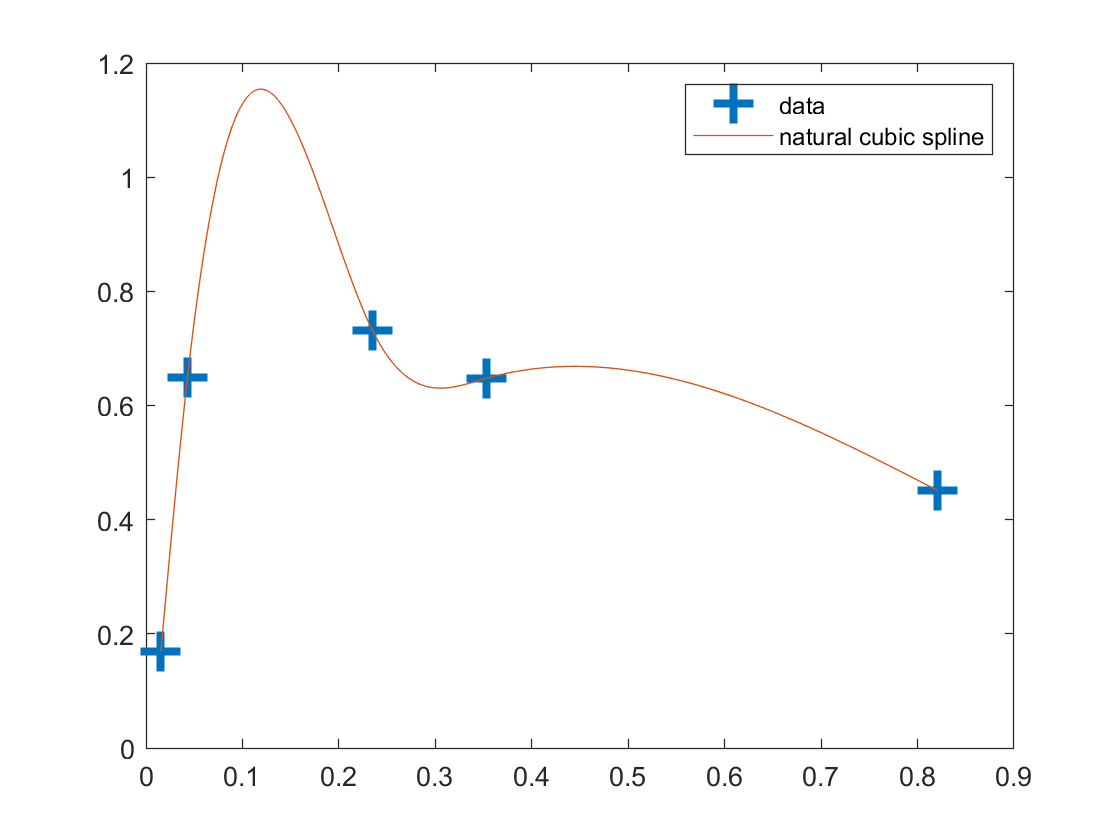

fig = figure();
ax = axes(fig, 'NextPlot','add','Box','on');
hline0 = plot(ax, data_x, data_y, 'LineStyle', 'none', 'Marker', '+', 'MarkerSize', 15,'LineWidth',3);

tmp1 = my_cubic_spline(data_x, data_y, interp_x);
hline1 = plot(ax, interp_x, tmp1);

legend([hline0,hline1],{'data', 'natural cubic spline'})

# function

function ret = my_cubic_spline(x0, y0, x)
% x0(N0,1) y0(N0,1) x(N1,1)
% ret(N1,1)
% reference: https://en.wikipedia.org/wiki/Spline_(mathematics)#Natural_continuity
N0 = size(x0,1);
assert(N0>1, 'cubic_spline requires at least two points');

tmp1 = all(x>=min(x0(:))) && all(x<=max(x0(:)));
assert(tmp1, 'cubic_spline require all x point sit between [min(x), max(x)]');

tmp1 = sortrows([x0,y0]);
x0 = tmp1(:,1);
y0 = tmp1(:,2);
delta_x = x0(2:end) - x0(1:(end-1));

tmp1 = [delta_x(1:end-1),(delta_x(1:(end-1))+delta_x(2:end))*2,delta_x(2:end)];
tmp2 = full(spdiags(tmp1, [0;1;2], N0-2, N0));
matA = [1,zeros(1,N0-1);tmp2;zeros(1,N0-1),1];

tmp1 = (y0(2:end) - y0(1:(end-1)))./delta_x;
matb = [0;6*(tmp1(2:end)-tmp1(1:(end-1)));0];
params = matA\matb;
ret = zeros(size(x));
for ind1 = 1:numel(x)
    ind2 = min(find(x(ind1)>=x0, 1, 'last'), N0-1);
    h = delta_x(ind2);
    lambda = (x0(ind2+1)-x(ind1))/h;
    omega = 1 - lambda;
    ret(ind1) = y0(ind2)*lambda + y0(ind2+1)*omega + params(ind2)*h^2/6*(lambda^3-lambda) ...
        + params(ind2+1)*h^2/6*(omega^3-omega);
end
end